clear;
load("Data\data_all.mat");
class_labels=0:9;

M = 64;
num_classes=10;
C = []; % Initialize centroid matrix
C_labels = repelem(0:num_classes-1, M)';
tic;
for i = 1:num_classes
    trainvi = trainv(trainlab == (i - 1), :); 
    [~, Ci] = kmeans(trainvi, M);
    C = [C; Ci];
end

K = 1;
predicted_labels_knn = knn_classifier(C, C_labels, testv, K);
conf_matrix_knn = confusionmat(testlab, predicted_labels_knn);
error_rate_knn = 1 - sum(diag(conf_matrix_knn)) / sum(conf_matrix_knn(:));

tid=toc;
time_str = datestr(seconds(tid), 'HH:MM:SS');

fprintf('Training time: %s\n', time_str);

Training time: 00:00:04


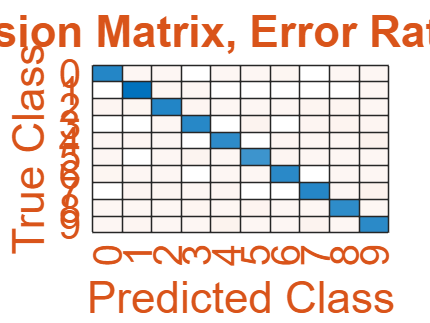

figure;
confusionchart(conf_matrix_knn, class_labels,'FontColor','0.85,0.33,0.10','FontSize',24);
title(['Confusion Matrix, Error Rate: ', num2str(round(error_rate_knn * 100,2)), '%']);